4. Dati contraexemple pentru convergenta interpolarii Lagrange si studiati-le grafic: 

(a) contraexemplul lui Runge $f:[-5,5]\rightarrow\mathbb{R}, f(x)=\frac{1}{1+x^2}$; 

(b) contraexemplul lui Bernstein $g:[-1,1]\rightarrow\mathbb{R}, g(x)=|x|$ ;

ambele cu noduri echidistante si noduri Cebisev de speta a doua.

% (a)

t = linspace(-5,5,100);
x = linspace(-1,1,10);
y = 1 ./ (1+x.*x);
pb = baryLagrange(x,y,t);
pf = ChebLagrange(y,x,-5,5)

pf =     0.9853    0.9892    0.9918    0.9932    0.9939    0.9939    0.9932    0.9918    0.9892    0.9853


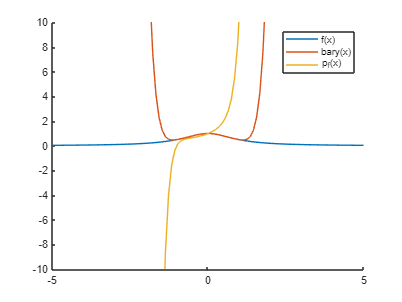


hold on
plot(t, 1 ./ (1+t.*t),"DisplayName","f(x)")           
plot(t, pb,"DisplayName",sprintf("bary(x)"))           
plot(t, polyval(pf,t),"DisplayName",sprintf("p_f(x)"))           
legend
ylim([[-10 10]])
hold off

% (b)

t = linspace(-1.5,1.5,100);
xx = linspace(-1,1,9);
y = abs(xx);
pg = ChebLagrange(y,xx,-1,1)

pg =     1.0000    0.5265    0.3598    0.1226         0    0.1226    0.3598    0.5265    1.0000


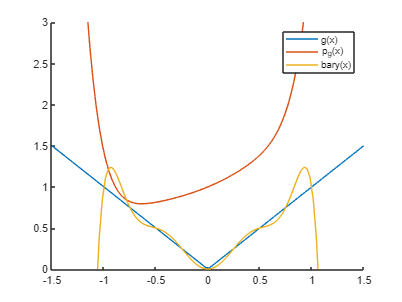

pb = baryLagrange(xx,y,t);

clf
hold on
plot(t, abs(t),"DisplayName","g(x)")           
plot(t, polyval(pg,t),"DisplayName",sprintf("p_g(x)"))           
plot(t, pb,"DisplayName",sprintf("bary(x)"))
legend
ylim([[0 3]])
hold off

function ff=ChebLagrange(y,xx,a,b)
    %CHEBLAGRANGE - Lagrange interpolation for Chebyshev points- barycentric
    %call ff=ChebLagrange(y,xx,a,b)
    %y - function values;
    %xx - evaluation points
    %a,b - interval
    %ff - values of Lagrange interpolation polynomial
    n = length(y)-1;
    if nargin==2
        a=-1; b=1;
    end
    c = [1/2; ones(n-1,1); 1/2].*(-1).^((0:n)');
    x = sort(cos((0:n)'*pi/n))*(b-a)/2+(a+b)/2;
    numer = zeros(size(xx));
    denom = zeros(size(xx));
    exact = zeros(size(xx));
    for j=1:n+1
        xdiff = xx-x(j);
        temp = c(j)./xdiff;
        numer = numer+temp*y(j);
        denom = denom+temp;
        exact(xdiff==0) = j;
    end
    ff = numer ./ denom;
    jj = find(exact);
    ff(jj) = y(exact(jj));
end


function ff=baryLagrange(x,y,xx)
    %BARYLAGRANGE - barycentric Lagrange interpolation
    %call ff=baryLagrange(x,y,xi)
    %x - nodes
    %y - function values
    %xx - interpolation points
    %ff - values of interpolation polynomial
    %compute weights
    n=length(x)-1;
    w=ones(1,n+1);
    for j=1:n+1
        c(j)=prod(x(j)-x([1:j-1,j+1:n+1]));
    end
    c=1./c;
    numer = zeros(size(xx));
    denom = zeros(size(xx));
    exact = zeros(size(xx));
    for j=1:n+1
        xdiff = xx-x(j);
        temp = c(j)./xdiff;
        numer = numer+temp*y(j);
        denom = denom+temp;
        exact(xdiff==0) = j;
    end
    ff = numer ./ denom;
    jj = find(exact);
    ff(jj) = y(exact(jj));
end